Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\User\eeg_options.m
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" v3.7.9 to the path - new version 3.8.1 available
EEGLAB: adding "ICLabel" v1.4 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.8 (see >> help eegplugin_clean_rawdata)
EEGLAB: adding "dipfit" v5.0 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.7.1 (see >> help eegplugin_firfilt)


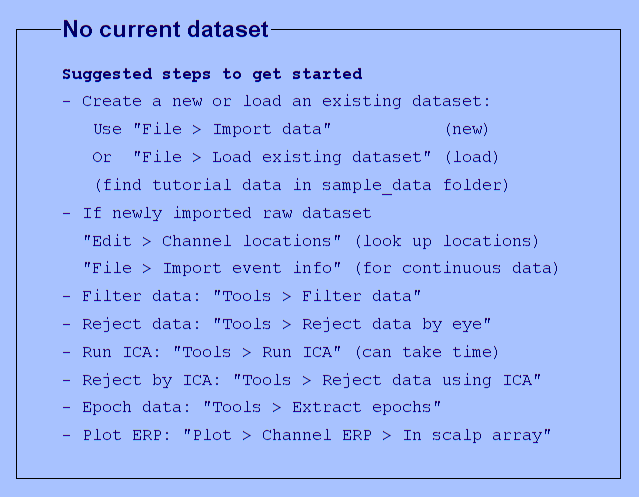

You are using the latest version of EEGLAB.


addpath 'C:\Users\User\Cloud-Drive\BigFiles\libs\eeglab2023.0'
addpath 'C:\Users\User\Cloud-Drive\BigFiles\libs'
eeglab


imported_events_output_dir = 'C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events';
imported_preproce_name =  'orig';
imported_filename_ses_types = {'sleep1','sleep2','sleep3','sleep4','sleep5','wake_morning','wake_night'};
imported_input_dir = 'C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported';
subs = {'01','02','03','04','05','06','07','08','09','10','11','12','13','14','15','16','17','19','20','21','22','23','24','25','26','27','28','29','30','31','32','33','34','35','36','37','38'};

for sub_ind=1:size(subs,2)
    for filename_ses_type_ind = 1:size(imported_filename_ses_types,2)
        output_filename = sprintf('%s\\s_%s_%s_%s_events.mat',imported_events_output_dir,subs{sub_ind},imported_filename_ses_types{filename_ses_type_ind},imported_preproce_name);
        if isfile(output_filename)
            string(strcat('Sub_',subs(sub_ind), ' already exists in path:',  output_filename))
            continue
        end
    
        %% get imported file elaborated event table
        set_filename = sprintf('%s\\s_%s_%s_%s.set',imported_input_dir,subs{sub_ind},imported_filename_ses_types{filename_ses_type_ind},imported_preproce_name);
        if ~isfile(set_filename) continue; end

        try
            eeglab_imported =  pop_loadset(set_filename);
            events = eeglab_imported.event;
            if ~isfolder(imported_events_output_dir)  mkdir(imported_events_output_dir); end
            save(output_filename,"events");
        catch ME
            strcat('could not get ' ,set_filename)
            continue
        end    
    end
end

ans = "Sub_01 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_01_sleep1_orig_events.mat"

ans = "Sub_01 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_01_sleep2_orig_events.mat"

ans = "Sub_01 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_01_sleep3_orig_events.mat"

ans = "Sub_01 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_01_wake_morning_orig_events.mat"

ans = "Sub_01 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_01_wake_night_orig_events.mat"

ans = "Sub_02 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_02_sleep1_orig_events.mat"

ans = "Sub_02 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_02_sleep2_orig_events.mat"

ans = "Sub_02 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_02_wake_morning_orig_events.mat"

ans = "Sub_02 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_02_wake_night_orig_events.mat"

ans = "Sub_03 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_03_sleep1_orig_events.mat"

ans = "Sub_03 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_03_sleep2_orig_events.mat"

ans = "Sub_03 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_03_wake_morning_orig_events.mat"

ans = "Sub_03 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_03_wake_night_orig_events.mat"

ans = "Sub_04 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_04_sleep1_orig_events.mat"

ans = "Sub_04 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_04_sleep2_orig_events.mat"

ans = "Sub_04 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_04_wake_morning_orig_events.mat"

ans = "Sub_04 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_04_wake_night_orig_events.mat"

ans = "Sub_05 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_05_sleep1_orig_events.mat"

ans = "Sub_05 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_05_wake_morning_orig_events.mat"

ans = "Sub_05 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_05_wake_night_orig_events.mat"

ans = "Sub_06 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_06_sleep1_orig_events.mat"

ans = "Sub_06 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_06_sleep2_orig_events.mat"

ans = "Sub_06 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_06_sleep3_orig_events.mat"

ans = "Sub_06 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_06_sleep4_orig_events.mat"

ans = "Sub_06 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_06_wake_morning_orig_events.mat"

ans = "Sub_06 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_06_wake_night_orig_events.mat"

ans = "Sub_07 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_07_sleep1_orig_events.mat"

ans = "Sub_07 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_07_sleep2_orig_events.mat"

ans = "Sub_07 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_07_sleep3_orig_events.mat"

ans = "Sub_07 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_07_wake_morning_orig_events.mat"

ans = "Sub_07 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_07_wake_night_orig_events.mat"

ans = "Sub_08 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_08_sleep1_orig_events.mat"

ans = "Sub_08 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_08_sleep2_orig_events.mat"

ans = "Sub_08 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_08_sleep3_orig_events.mat"

ans = "Sub_08 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_08_sleep4_orig_events.mat"

ans = "Sub_08 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_08_sleep5_orig_events.mat"

ans = "Sub_08 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_08_wake_morning_orig_events.mat"

ans = "Sub_08 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_08_wake_night_orig_events.mat"

ans = "Sub_09 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_09_sleep1_orig_events.mat"

ans = "Sub_09 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_09_sleep2_orig_events.mat"

ans = "Sub_09 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_09_sleep3_orig_events.mat"

ans = "Sub_09 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_09_wake_morning_orig_events.mat"

ans = "Sub_09 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_09_wake_night_orig_events.mat"

ans = "Sub_10 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_10_sleep1_orig_events.mat"

ans = "Sub_10 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_10_sleep2_orig_events.mat"

ans = "Sub_10 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_10_sleep3_orig_events.mat"

ans = "Sub_10 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_10_sleep4_orig_events.mat"

ans = "Sub_10 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_10_wake_morning_orig_events.mat"

ans = "Sub_10 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_10_wake_night_orig_events.mat"

ans = "Sub_11 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_11_sleep1_orig_events.mat"

ans = "Sub_11 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_11_sleep2_orig_events.mat"

ans = "Sub_11 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_11_sleep3_orig_events.mat"

ans = "Sub_11 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_11_wake_morning_orig_events.mat"

ans = "Sub_11 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_11_wake_night_orig_events.mat"

ans = "Sub_12 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_12_sleep1_orig_events.mat"

ans = "Sub_12 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_12_sleep2_orig_events.mat"

ans = "Sub_12 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_12_wake_morning_orig_events.mat"

ans = "Sub_12 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_12_wake_night_orig_events.mat"

ans = "Sub_13 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_13_sleep1_orig_events.mat"

ans = "Sub_13 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_13_sleep2_orig_events.mat"

ans = "Sub_13 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_13_sleep3_orig_events.mat"

ans = "Sub_13 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_13_sleep4_orig_events.mat"

ans = "Sub_13 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_13_wake_morning_orig_events.mat"

ans = "Sub_13 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_13_wake_night_orig_events.mat"

ans = "Sub_14 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_14_sleep1_orig_events.mat"

ans = "Sub_14 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_14_sleep2_orig_events.mat"

ans = "Sub_14 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_14_sleep3_orig_events.mat"

ans = "Sub_14 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_14_sleep4_orig_events.mat"

ans = "Sub_14 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_14_sleep5_orig_events.mat"

ans = "Sub_14 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_14_wake_morning_orig_events.mat"

ans = "Sub_14 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_14_wake_night_orig_events.mat"

ans = "Sub_15 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_15_sleep1_orig_events.mat"

ans = "Sub_15 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_15_sleep2_orig_events.mat"

ans = "Sub_15 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_15_sleep3_orig_events.mat"

ans = "Sub_15 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_15_wake_morning_orig_events.mat"

ans = "Sub_15 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_15_wake_night_orig_events.mat"

ans = "Sub_16 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_16_sleep1_orig_events.mat"

ans = "Sub_16 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_16_sleep2_orig_events.mat"

ans = "Sub_16 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_16_sleep3_orig_events.mat"

ans = "Sub_16 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_16_sleep4_orig_events.mat"

ans = "Sub_16 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_16_wake_morning_orig_events.mat"

ans = "Sub_16 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_16_wake_night_orig_events.mat"

ans = "Sub_17 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_17_sleep1_orig_events.mat"

ans = "Sub_17 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_17_sleep2_orig_events.mat"

ans = "Sub_17 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_17_wake_morning_orig_events.mat"

ans = "Sub_17 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_17_wake_night_orig_events.mat"

ans = "Sub_19 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_19_sleep1_orig_events.mat"

ans = "Sub_19 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_19_sleep2_orig_events.mat"

ans = "Sub_19 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_19_sleep3_orig_events.mat"

ans = "Sub_19 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_19_sleep4_orig_events.mat"

ans = "Sub_19 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_19_wake_morning_orig_events.mat"

ans = "Sub_19 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_19_wake_night_orig_events.mat"

ans = "Sub_20 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_20_sleep1_orig_events.mat"

ans = "Sub_20 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_20_sleep2_orig_events.mat"

ans = "Sub_20 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_20_sleep3_orig_events.mat"

ans = "Sub_20 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_20_sleep4_orig_events.mat"

ans = "Sub_20 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_20_wake_morning_orig_events.mat"

ans = "Sub_20 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_20_wake_night_orig_events.mat"

ans = "Sub_21 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_21_sleep1_orig_events.mat"

ans = "Sub_21 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_21_sleep2_orig_events.mat"

ans = "Sub_21 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_21_sleep3_orig_events.mat"

ans = "Sub_21 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_21_sleep4_orig_events.mat"

ans = "Sub_21 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_21_sleep5_orig_events.mat"

ans = "Sub_21 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_21_wake_morning_orig_events.mat"

ans = "Sub_21 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_21_wake_night_orig_events.mat"

ans = "Sub_22 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_22_sleep1_orig_events.mat"

ans = "Sub_22 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_22_sleep2_orig_events.mat"

ans = "Sub_22 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_22_sleep3_orig_events.mat"

ans = "Sub_22 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_22_sleep4_orig_events.mat"

ans = "Sub_22 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_22_wake_morning_orig_events.mat"

ans = "Sub_22 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_22_wake_night_orig_events.mat"

ans = "Sub_23 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_23_sleep1_orig_events.mat"

ans = "Sub_23 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_23_sleep2_orig_events.mat"

ans = "Sub_23 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_23_sleep3_orig_events.mat"

ans = "Sub_23 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_23_wake_morning_orig_events.mat"

ans = "Sub_23 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_23_wake_night_orig_events.mat"

ans = "Sub_24 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_24_sleep1_orig_events.mat"

ans = "Sub_24 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_24_sleep2_orig_events.mat"

ans = "Sub_24 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_24_sleep3_orig_events.mat"

ans = "Sub_24 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_24_sleep4_orig_events.mat"

ans = "Sub_24 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_24_wake_morning_orig_events.mat"

ans = "Sub_24 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_24_wake_night_orig_events.mat"

ans = "Sub_25 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_25_sleep1_orig_events.mat"

ans = "Sub_25 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_25_sleep2_orig_events.mat"

ans = "Sub_25 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_25_sleep3_orig_events.mat"

ans = "Sub_25 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_25_sleep4_orig_events.mat"

ans = "Sub_25 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_25_wake_morning_orig_events.mat"

ans = "Sub_25 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_25_wake_night_orig_events.mat"

ans = "Sub_26 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_26_sleep1_orig_events.mat"

ans = "Sub_26 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_26_sleep2_orig_events.mat"

ans = "Sub_26 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_26_wake_morning_orig_events.mat"

ans = "Sub_26 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_26_wake_night_orig_events.mat"

ans = "Sub_27 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_27_sleep1_orig_events.mat"

ans = "Sub_27 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_27_sleep2_orig_events.mat"

ans = "Sub_27 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_27_sleep3_orig_events.mat"

ans = "Sub_27 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_27_wake_morning_orig_events.mat"

ans = "Sub_27 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_27_wake_night_orig_events.mat"

ans = "Sub_28 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_28_sleep1_orig_events.mat"

ans = "Sub_28 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_28_sleep2_orig_events.mat"

ans = "Sub_28 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_28_sleep3_orig_events.mat"

ans = "Sub_28 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_28_sleep4_orig_events.mat"

ans = "Sub_28 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_28_sleep5_orig_events.mat"

ans = "Sub_28 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_28_wake_morning_orig_events.mat"

ans = "Sub_28 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_28_wake_night_orig_events.mat"

ans = "Sub_29 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_29_sleep1_orig_events.mat"

ans = "Sub_29 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_29_sleep2_orig_events.mat"

ans = "Sub_29 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_29_sleep3_orig_events.mat"

ans = "Sub_29 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_29_wake_morning_orig_events.mat"

ans = "Sub_29 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_29_wake_night_orig_events.mat"

ans = "Sub_30 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_30_sleep1_orig_events.mat"

ans = "Sub_30 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_30_sleep2_orig_events.mat"

ans = "Sub_30 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_30_sleep3_orig_events.mat"

ans = "Sub_30 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_30_sleep4_orig_events.mat"

ans = "Sub_30 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_30_wake_morning_orig_events.mat"

ans = "Sub_30 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_30_wake_night_orig_events.mat"

ans = "Sub_31 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_31_sleep1_orig_events.mat"

ans = "Sub_31 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_31_sleep2_orig_events.mat"

ans = "Sub_31 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_31_sleep3_orig_events.mat"

ans = "Sub_31 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_31_sleep4_orig_events.mat"

ans = "Sub_31 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_31_wake_morning_orig_events.mat"

ans = "Sub_31 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_31_wake_night_orig_events.mat"

ans = "Sub_32 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_32_sleep1_orig_events.mat"

ans = "Sub_32 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_32_sleep2_orig_events.mat"

ans = "Sub_32 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_32_sleep3_orig_events.mat"

ans = "Sub_32 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_32_wake_morning_orig_events.mat"

ans = "Sub_32 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_32_wake_night_orig_events.mat"

ans = "Sub_33 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_33_sleep1_orig_events.mat"

ans = "Sub_33 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_33_sleep2_orig_events.mat"

ans = "Sub_33 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_33_sleep3_orig_events.mat"

ans = "Sub_33 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_33_sleep4_orig_events.mat"

ans = "Sub_33 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_33_wake_morning_orig_events.mat"

ans = "Sub_33 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_33_wake_night_orig_events.mat"

ans = "Sub_34 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_34_sleep1_orig_events.mat"

ans = "Sub_34 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_34_sleep2_orig_events.mat"

ans = "Sub_34 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_34_sleep3_orig_events.mat"

ans = "Sub_34 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_34_wake_morning_orig_events.mat"

ans = "Sub_34 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_34_wake_night_orig_events.mat"

ans = "Sub_35 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_35_sleep1_orig_events.mat"

ans = "Sub_35 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_35_sleep2_orig_events.mat"

ans = "Sub_35 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_35_sleep3_orig_events.mat"

ans = "Sub_35 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_35_sleep4_orig_events.mat"

ans = "Sub_35 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_35_wake_morning_orig_events.mat"

ans = "Sub_35 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_35_wake_night_orig_events.mat"

ans = "Sub_36 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_36_sleep1_orig_events.mat"

ans = "Sub_36 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_36_sleep2_orig_events.mat"

ans = "Sub_36 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_36_sleep3_orig_events.mat"

ans = "Sub_36 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_36_wake_morning_orig_events.mat"

ans = "Sub_36 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_36_wake_night_orig_events.mat"

ans = "Sub_37 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_37_sleep1_orig_events.mat"

ans = "Sub_37 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_37_sleep2_orig_events.mat"

ans = "Sub_37 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_37_sleep3_orig_events.mat"

ans = "Sub_37 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_37_wake_morning_orig_events.mat"

ans = "Sub_37 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_37_wake_night_orig_events.mat"

ans = "Sub_38 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_38_sleep1_orig_events.mat"

ans = "Sub_38 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_38_sleep2_orig_events.mat"

ans = "Sub_38 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_38_sleep3_orig_events.mat"

ans = "Sub_38 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_38_wake_morning_orig_events.mat"

ans = "Sub_38 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\events\s_38_wake_night_orig_events.mat"

reref_events_output_dir = 'C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events';
referenced_preproce_name =  'referenced';
referenced_filename_ses_types = {'sleep','wake_morning','wake_night'};
referenced_input_dir = 'C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced';
subs = {'01','02','03','04','05','06','07','08','09','10','11','12','13','14','15','16','17','18','19','20','21','22','23','24','25','26','27','28','29','30','31','32','33','34','35','36','37','38'};

for sub_ind=1:size(subs,2)
    for filename_ses_type_ind = 1:size(referenced_filename_ses_types,2)
        output_filename = sprintf('%s\\s_%s_%s_%s_events.mat',reref_events_output_dir,subs{sub_ind},referenced_filename_ses_types{filename_ses_type_ind},referenced_preproce_name);
        if isfile(output_filename)
            string(strcat('Sub_',subs(sub_ind), ' already exists in path:',  output_filename))
            continue
        end
        set_filename = sprintf('%s\\s_%s_%s_%s.set',referenced_input_dir,subs{sub_ind},referenced_filename_ses_types{filename_ses_type_ind},referenced_preproce_name);
        if ~isfile(set_filename) continue; end

        try
            eeglab_imported =  pop_loadset(set_filename);
            events = eeglab_imported.event;
            if ~isfolder(reref_events_output_dir)  mkdir(reref_events_output_dir); end
            save(output_filename,"events");
        catch ME
            strcat('could not get ' ,set_filename)
        end    
    end
end

ans = "Sub_01 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_01_sleep_referenced_events.mat"

ans = "Sub_01 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_01_wake_morning_referenced_events.mat"

ans = "Sub_01 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_01_wake_night_referenced_events.mat"

ans = "Sub_02 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_02_sleep_referenced_events.mat"

ans = "Sub_02 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_02_wake_morning_referenced_events.mat"

ans = "Sub_02 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_02_wake_night_referenced_events.mat"

ans = "Sub_03 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_03_sleep_referenced_events.mat"

ans = "Sub_03 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_03_wake_morning_referenced_events.mat"

ans = "Sub_03 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_03_wake_night_referenced_events.mat"

ans = "Sub_04 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_04_sleep_referenced_events.mat"

ans = "Sub_04 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_04_wake_morning_referenced_events.mat"

ans = "Sub_04 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_04_wake_night_referenced_events.mat"

ans = "Sub_05 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_05_sleep_referenced_events.mat"

ans = "Sub_05 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_05_wake_morning_referenced_events.mat"

ans = "Sub_05 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_05_wake_night_referenced_events.mat"

ans = "Sub_06 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_06_sleep_referenced_events.mat"

ans = "Sub_06 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_06_wake_morning_referenced_events.mat"

ans = "Sub_06 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_06_wake_night_referenced_events.mat"

ans = "Sub_07 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_07_sleep_referenced_events.mat"

ans = "Sub_07 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_07_wake_morning_referenced_events.mat"

ans = "Sub_07 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_07_wake_night_referenced_events.mat"

ans = "Sub_08 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_08_sleep_referenced_events.mat"

ans = "Sub_08 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_08_wake_morning_referenced_events.mat"

ans = "Sub_08 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_08_wake_night_referenced_events.mat"

ans = "Sub_09 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_09_sleep_referenced_events.mat"

ans = "Sub_09 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_09_wake_morning_referenced_events.mat"

ans = "Sub_09 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_09_wake_night_referenced_events.mat"

ans = "Sub_10 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_10_sleep_referenced_events.mat"

ans = "Sub_10 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_10_wake_morning_referenced_events.mat"

ans = "Sub_10 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_10_wake_night_referenced_events.mat"

ans = "Sub_11 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_11_sleep_referenced_events.mat"

ans = "Sub_11 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_11_wake_morning_referenced_events.mat"

ans = "Sub_11 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_11_wake_night_referenced_events.mat"

ans = "Sub_12 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_12_sleep_referenced_events.mat"

ans = "Sub_12 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_12_wake_morning_referenced_events.mat"

ans = "Sub_12 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_12_wake_night_referenced_events.mat"

ans = "Sub_13 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_13_sleep_referenced_events.mat"

ans = "Sub_13 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_13_wake_morning_referenced_events.mat"

ans = "Sub_13 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_13_wake_night_referenced_events.mat"

ans = "Sub_14 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_14_sleep_referenced_events.mat"

ans = "Sub_14 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_14_wake_morning_referenced_events.mat"

ans = "Sub_14 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_14_wake_night_referenced_events.mat"

ans = "Sub_15 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_15_sleep_referenced_events.mat"

ans = "Sub_15 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_15_wake_morning_referenced_events.mat"

ans = "Sub_15 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_15_wake_night_referenced_events.mat"

ans = "Sub_16 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_16_sleep_referenced_events.mat"

ans = "Sub_16 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_16_wake_morning_referenced_events.mat"

ans = "Sub_16 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_16_wake_night_referenced_events.mat"

ans = "Sub_17 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_17_sleep_referenced_events.mat"

ans = "Sub_17 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_17_wake_morning_referenced_events.mat"

ans = "Sub_17 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_17_wake_night_referenced_events.mat"

ans = "Sub_19 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_19_sleep_referenced_events.mat"

ans = "Sub_19 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_19_wake_morning_referenced_events.mat"

ans = "Sub_19 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_19_wake_night_referenced_events.mat"

ans = "Sub_20 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_20_sleep_referenced_events.mat"

ans = "Sub_20 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_20_wake_morning_referenced_events.mat"

ans = "Sub_20 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_20_wake_night_referenced_events.mat"

ans = "Sub_21 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_21_sleep_referenced_events.mat"

ans = "Sub_21 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_21_wake_morning_referenced_events.mat"

ans = "Sub_21 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_21_wake_night_referenced_events.mat"

ans = "Sub_22 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_22_sleep_referenced_events.mat"

ans = "Sub_22 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_22_wake_morning_referenced_events.mat"

ans = "Sub_22 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_22_wake_night_referenced_events.mat"

ans = "Sub_23 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_23_sleep_referenced_events.mat"

ans = "Sub_23 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_23_wake_morning_referenced_events.mat"

ans = "Sub_23 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_23_wake_night_referenced_events.mat"

ans = "Sub_24 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_24_sleep_referenced_events.mat"

ans = "Sub_24 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_24_wake_morning_referenced_events.mat"

ans = "Sub_24 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_24_wake_night_referenced_events.mat"

ans = "Sub_25 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_25_sleep_referenced_events.mat"

ans = "Sub_25 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_25_wake_morning_referenced_events.mat"

ans = "Sub_25 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_25_wake_night_referenced_events.mat"

ans = "Sub_26 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_26_sleep_referenced_events.mat"

ans = "Sub_26 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_26_wake_morning_referenced_events.mat"

ans = "Sub_26 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_26_wake_night_referenced_events.mat"

ans = "Sub_27 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_27_sleep_referenced_events.mat"

ans = "Sub_27 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_27_wake_morning_referenced_events.mat"

ans = "Sub_27 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_27_wake_night_referenced_events.mat"

ans = "Sub_28 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_28_sleep_referenced_events.mat"

ans = "Sub_28 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_28_wake_morning_referenced_events.mat"

ans = "Sub_28 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_28_wake_night_referenced_events.mat"

ans = "Sub_29 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_29_sleep_referenced_events.mat"

ans = "Sub_29 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_29_wake_morning_referenced_events.mat"

ans = "Sub_29 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_29_wake_night_referenced_events.mat"

ans = "Sub_30 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_30_sleep_referenced_events.mat"

ans = "Sub_30 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_30_wake_morning_referenced_events.mat"

ans = "Sub_30 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_30_wake_night_referenced_events.mat"

ans = "Sub_31 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_31_sleep_referenced_events.mat"

ans = "Sub_31 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_31_wake_morning_referenced_events.mat"

ans = "Sub_31 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_31_wake_night_referenced_events.mat"

ans = "Sub_32 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_32_sleep_referenced_events.mat"

ans = "Sub_32 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_32_wake_morning_referenced_events.mat"

ans = "Sub_32 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_32_wake_night_referenced_events.mat"

ans = "Sub_33 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_33_sleep_referenced_events.mat"

ans = "Sub_33 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_33_wake_morning_referenced_events.mat"

ans = "Sub_33 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_33_wake_night_referenced_events.mat"

ans = "Sub_34 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_34_sleep_referenced_events.mat"

ans = "Sub_34 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_34_wake_morning_referenced_events.mat"

ans = "Sub_34 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_34_wake_night_referenced_events.mat"

ans = "Sub_35 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_35_sleep_referenced_events.mat"

ans = "Sub_35 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_35_wake_morning_referenced_events.mat"

ans = "Sub_35 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_35_wake_night_referenced_events.mat"

ans = "Sub_36 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_36_sleep_referenced_events.mat"

ans = "Sub_36 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_36_wake_morning_referenced_events.mat"

ans = "Sub_36 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_36_wake_night_referenced_events.mat"

ans = "Sub_37 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_37_sleep_referenced_events.mat"

ans = "Sub_37 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_37_wake_morning_referenced_events.mat"

ans = "Sub_37 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_37_wake_night_referenced_events.mat"

ans = "Sub_38 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_38_sleep_referenced_events.mat"

ans = "Sub_38 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_38_wake_morning_referenced_events.mat"

ans = "Sub_38 already exists in path:C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\events\s_38_wake_night_referenced_events.mat"